## 一阶倒立摆系统的H-infinty状态反馈控制

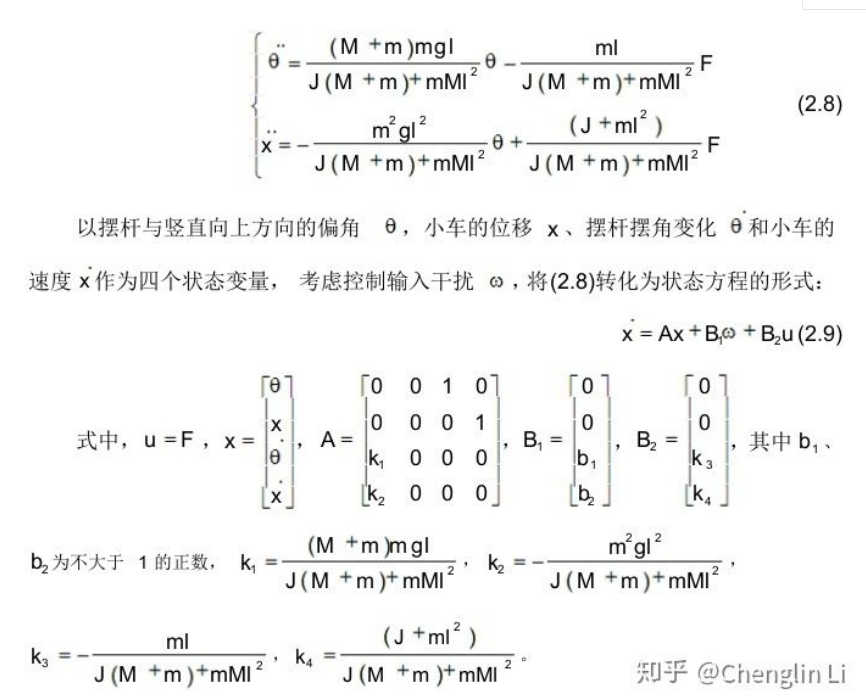

clear;
M=1; %小车质量
m=0.1; %倒立摆质量
L=0.5; %摆的长度
g=9.8 ;%重力加速度
J=m*L^2/3; %转动惯量

k=J*(M+m)+m*M*L^2 ;
k1=(M+m)*m*g*L/k ;
k2=-m^2*g*L^2/k ;
k3=-m*L/k ;
k4=( J+m*L^2 ) /k ; %中间变量

%------对象描述------------
A=[0,0,1,0 ;
   0,0,0,1 ;
   k1,0,0,0;
   k2,0,0,0];
%     B1=[0; 0; 0.09; 0.11 ];
B1=[0;0;0.2;0.2] ;
B2=[0; 0; k3; k4];
C1=[1,0,0,0; 
    0,1,0,0; 
    0,0,1,0; 
    0,0,0,1;] ;

D11=[0;0;0;0];
D12=D11;


#### 最优解

#### 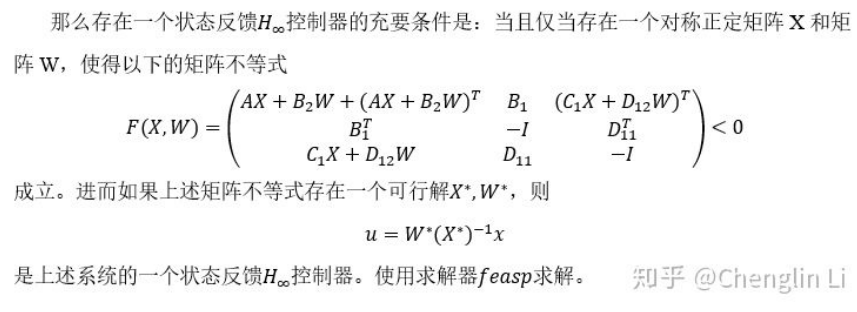

pvar theta x d_theta dx;
vars = [theta; x; d_theta; dx];
prog = sosprogram(vars);
[prog,X] = sospolymatrixvar(prog,monomials(vars,0),[4,4],'symmetric');
[prog,W] = sospolymatrixvar(prog,monomials(vars,0),[1,4]);

% F = [A*X+B2*W+(A*X+B2*W)' , B1       , (C1*X+D12*W)';
%     B1'                   , -1  ,          D11'     ;
%     C1*X+D12*W            ,D11       ,   -eye(4)    ];
% eps1 = 1e-5;
% 
% %添加约束
% prog = sosmatrixineq(prog, -F-eps1, 'quadraticMineq');
% prog = sosmatrixineq(prog, X-eps1, 'quadraticMineq');
% %设置目标问题min
% % prog = sossetobj(prog, *);
% %求解
% prog = sossolve(prog);
% %返回值
% X = double(sosgetsol(prog,X))
% W = double(sosgetsol(prog,W))
% %状态反馈增益阵
% K = W/X

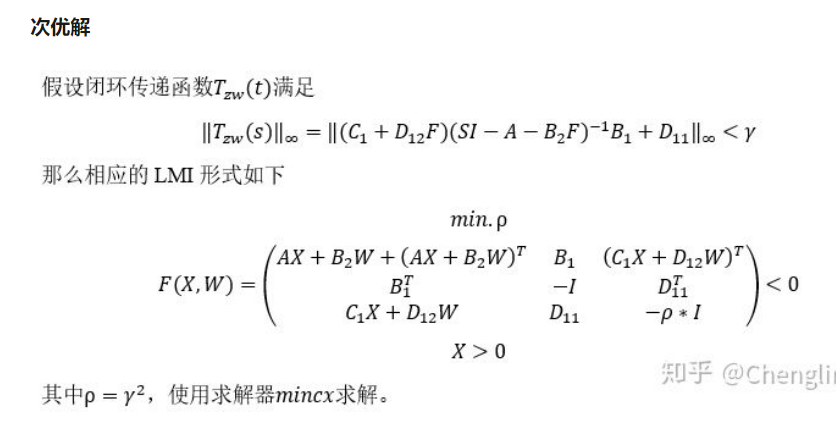

[prog,ro] = sospolymatrixvar(prog,monomials(vars,0),[1,1]);
% [prog,eps1] = sospolymatrixvar(prog,monomials(vars,0),[1,1]);
F1 = [A*X+B2*W+(A*X+B2*W)' , B1       , (C1*X+D12*W)';
     B1'                   , -1  ,          D11'     ;
     C1*X+D12*W            , D11       ,   -eye(4)*ro];
% eps1 = 1e-10;
%添加约束
% prog = sosmatrixineq(prog, eps1, 'quadraticMineq');
prog = sosmatrixineq(prog, X-(1e-7), 'quadraticMineq');
prog = sosmatrixineq(prog, ro-(1e-8), 'quadraticMineq');
prog = sosmatrixineq(prog, -F1-(1e-3), 'quadraticMineq');
%设置目标问题min
prog = sossetobj(prog, ro);
%求解
prog = sossolve(prog);

Size: 113   56
 
SeDuMi 1.3 by AdvOL, 2005-2008 and Jos F. Sturm, 1998-2003.
Alg = 2: xz-corrector, Adaptive Step-Differentiation, theta = 0.250, beta = 0.500
Put 15 free variables in a quadratic cone
eqs m = 56, order n = 17, dim = 115, blocks = 5
nnz(A) = 111 + 0, nnz(ADA) = 2806, nnz(L) = 1431
 it :     b*y       gap    delta  rate   t/tP*  t/tD*   feas cg cg  prec
  0 :            1.15E+00 0.000
  1 :   1.58E-01 3.17E-01 0.000 0.2764 0.9000 0.9000   1.88  1  1  1.3E+00
  2 :   2.82E-02 9.33E-02 0.000 0.2945 0.9000 0.9000   2.74  1  1  3.0E-01
  3 :   9.15E-03 2.39E-02 0.000 0.2564 0.9000 0.9000   1.41  1  1  1.6E-01
  4 :   6.54E-03 7.76E-03 0.000 0.3244 0.9000 0.9000   1.22  1  1  8.5E-02
  5 :   2.37E-02 2.26E-03 0.000 0.2911 0.9000 0.9000   0.33  1  1  5.2E-03
  6 :   3.48E-02 6.86E-04 0.000 0.3037 0.9000 0.9000   0.17  1  1  2.4E-03
  7 :   3.71E-02 2.28E-04 0.000 0.3327 0.9000 0.9000   0.46  1  1  1.0E-03
  8 :   3.77E-02 8.12E-05 0.000 0.3556 0.9000 0.9000   0.55  1  1  4.5E-

%返回值
X = double(sosgetsol(prog,X));
W = double(sosgetsol(prog,W));
ro = double(sosgetsol(prog,ro));
% eps1 = double(sosgetsol(prog,eps1))
gamma = sqrt(ro)

gamma = 0.1791

%状态反馈增益阵
K = W/X

K = 	1.0e+06 *

    5.6481    1.4697    1.2230    1.8246
